taus = [];
Ks = [];

Calibration 1

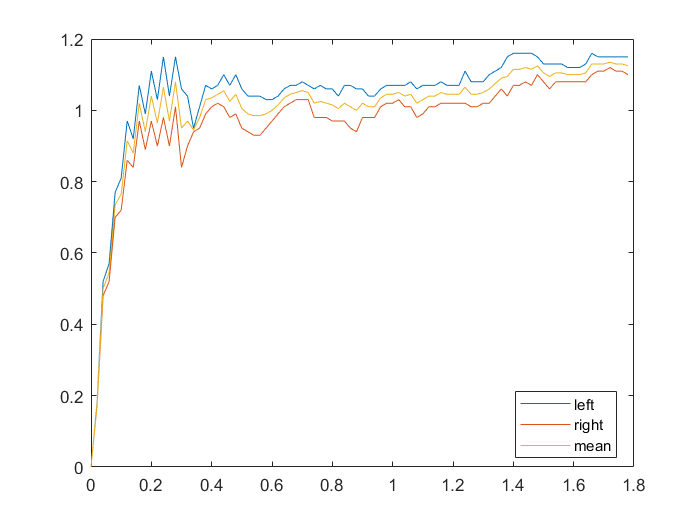


data = readtable('output_motor_cal1.txt');

L_vel = data.Var1;
R_vel = data.Var2;
R_vel = erase(R_vel,';');
R_vel = cellfun(@str2num,R_vel);
t = 0:0.02:10;

L_vel = L_vel(1:90);
R_vel = R_vel(1:90);
t = t(1:length(L_vel))';
V_mean = (L_vel + R_vel)/2;


figure()
plot(t, L_vel)
hold on
plot(t, R_vel)
plot(t, V_mean)
legend('left', 'right', 'mean', 'location', 'best')


V_time_domain = @(K, tau, t) Vdrive*K*(1-exp(-t/tau));

meanFit = createStepResponseFit(t, V_mean)

meanFit =      General model:
     meanFit(x) = 300*K*(1-exp(-x/tau))
     Coefficients (with 95% confidence bounds):
       K =    0.003513  (0.003477, 0.003548)
       tau =     0.07221  (0.06512, 0.07929)

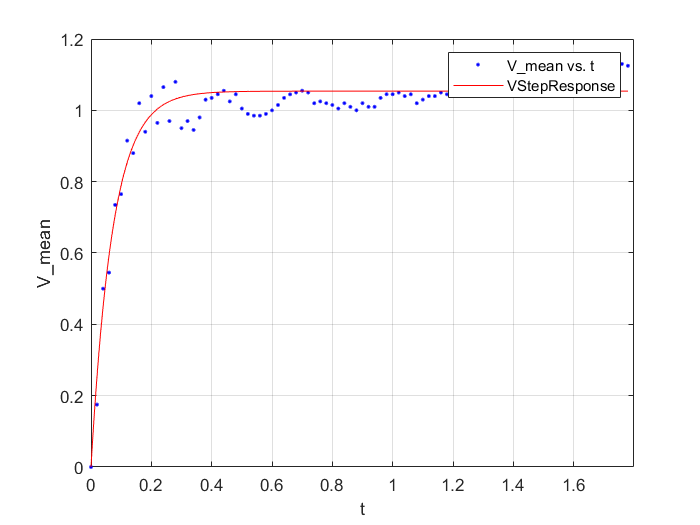

rightFit =      General model:
     rightFit(x) = 300*K*(1-exp(-x/tau))
     Coefficients (with 95% confidence bounds):
       K =    0.003394  (0.003353, 0.003435)
       tau =     0.07765  (0.06899, 0.08631)

taus = [taus; meanFit.tau];
Ks = [Ks; meanFit.K];

rightFit = createStepResponseFit(t, R_vel)

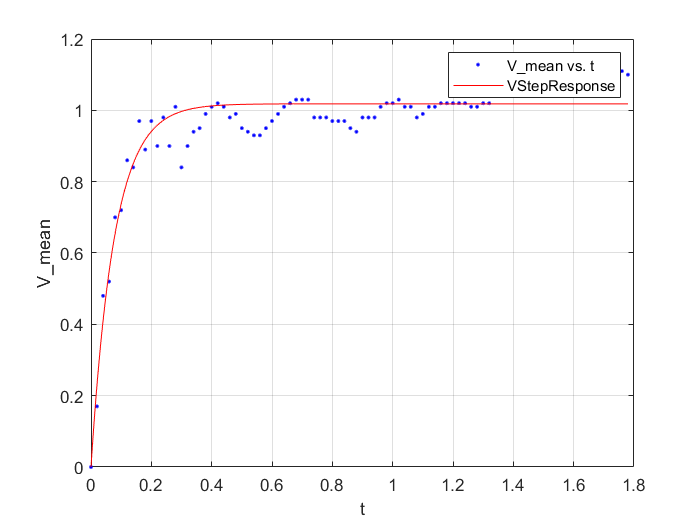

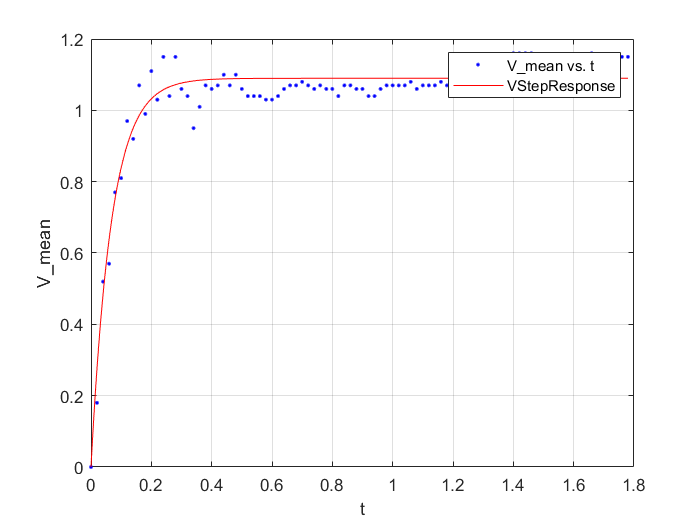

leftFit =      General model:
     leftFit(x) = 300*K*(1-exp(-x/tau))
     Coefficients (with 95% confidence bounds):
       K =    0.003633  (0.003598, 0.003667)
       tau =     0.06805  (0.06161, 0.0745)

leftFit = createStepResponseFit(t, L_vel)

Calibration 2

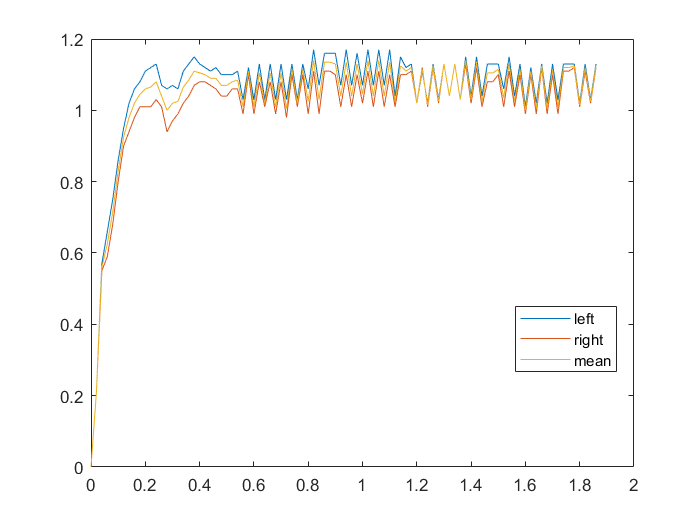

data = readtable('output_motor_cal2.txt');

L_vel = data.Var1;
R_vel = data.Var2;
R_vel = erase(R_vel,';');
R_vel = cellfun(@str2num,R_vel);
t = 0:0.02:10;

L_vel = L_vel(1:94);
R_vel = R_vel(1:94);
t = t(1:length(L_vel))';
V_mean = (L_vel + R_vel)/2;


figure()
plot(t, L_vel)
hold on
plot(t, R_vel)
plot(t, V_mean)
legend('left', 'right', 'mean', 'location', 'best')

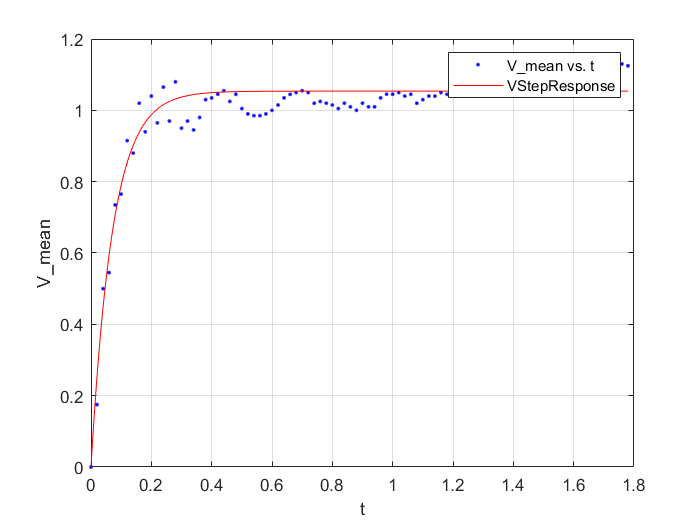

meanFit =      General model:
     meanFit(x) = 300*K*(1-exp(-x/tau))
     Coefficients (with 95% confidence bounds):
       K =    0.003598  (0.003564, 0.003633)
       tau =     0.06528  (0.05879, 0.07178)


V_time_domain = @(K, tau, t) Vdrive*K*(1-exp(-t/tau));

meanFit = createStepResponseFit(t, V_mean)

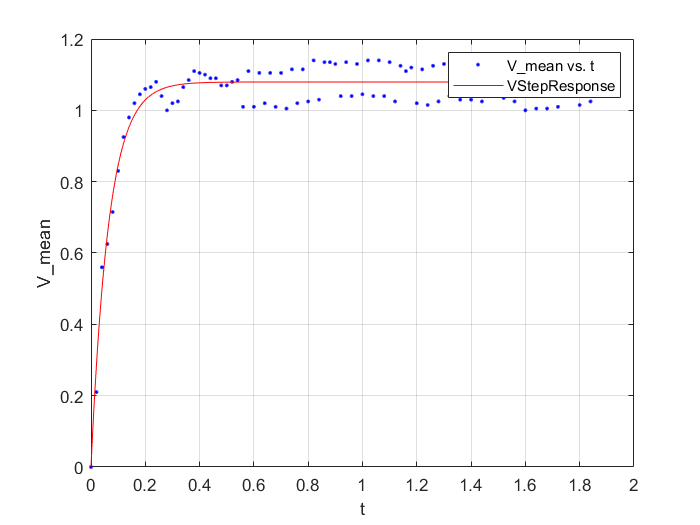

rightFit =      General model:
     rightFit(x) = 300*K*(1-exp(-x/tau))
     Coefficients (with 95% confidence bounds):
       K =    0.003531  (0.003495, 0.003567)
       tau =     0.06947  (0.06242, 0.07652)

taus = [taus; meanFit.tau];
Ks = [Ks; meanFit.K];
rightFit = createStepResponseFit(t, R_vel)

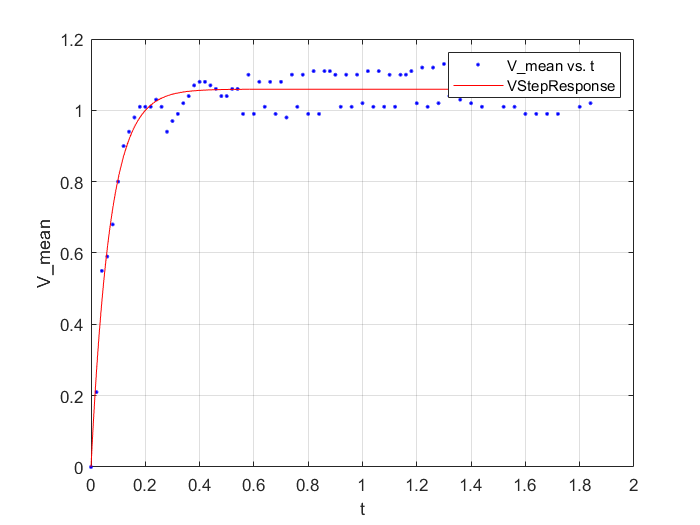

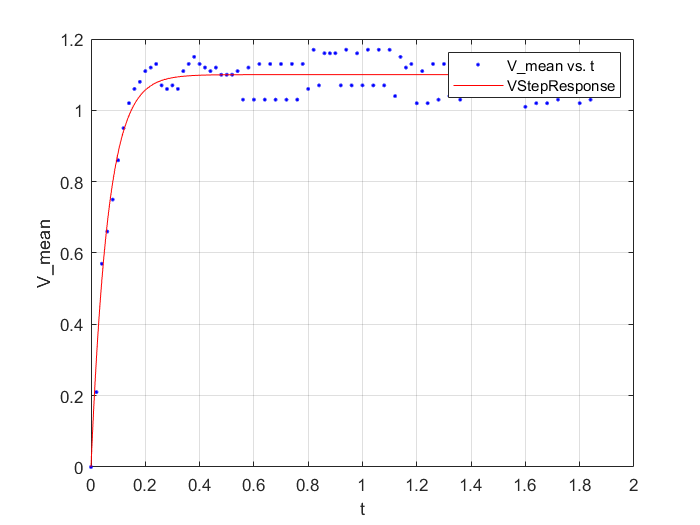

leftFit =      General model:
     leftFit(x) = 300*K*(1-exp(-x/tau))
     Coefficients (with 95% confidence bounds):
       K =    0.003667  (0.003631, 0.003703)
       tau =     0.06184  (0.05537, 0.0683)

leftFit = createStepResponseFit(t, L_vel)

Calibration 3

data = readtable('output_motor_cal3.txt');

L_vel = data.Var1

L_vel =          0
    0.2200
    0.5000
    0.6300
    0.7000
    0.8800
    0.8600
    1.0200
    0.9900
    1.1000


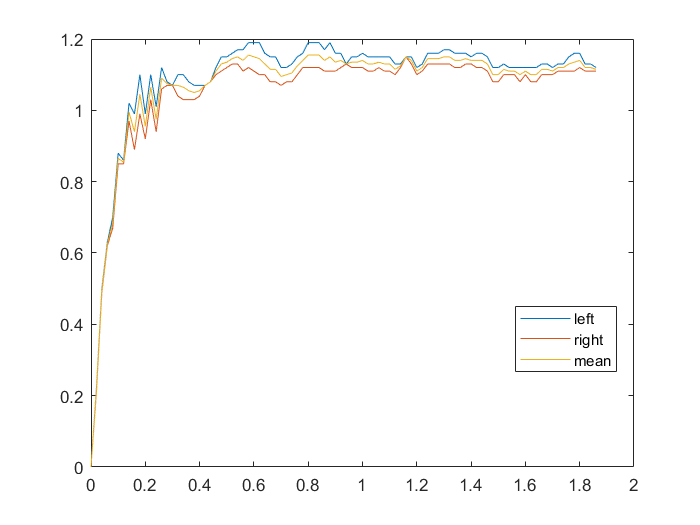

meanFit =      General model:
     meanFit(x) = 300*K*(1-exp(-x/tau))
     Coefficients (with 95% confidence bounds):
       K =    0.003744  (0.003724, 0.003765)
       tau =     0.07948  (0.07532, 0.08365)

R_vel = data.Var2;
R_vel = erase(R_vel,';');
R_vel = cellfun(@str2num,R_vel);
L_vel = L_vel(1:94);
R_vel = R_vel(1:94);
t = 0:0.02:10;
t = t(1:length(L_vel))';
V_mean = (L_vel + R_vel)/2;


figure()
plot(t, L_vel)
hold on
plot(t, R_vel)
plot(t, V_mean)
legend('left', 'right', 'mean', 'location', 'best')

V_time_domain = @(K, tau, t) Vdrive*K*(1-exp(-t/tau));

meanFit = createStepResponseFit(t, V_mean)

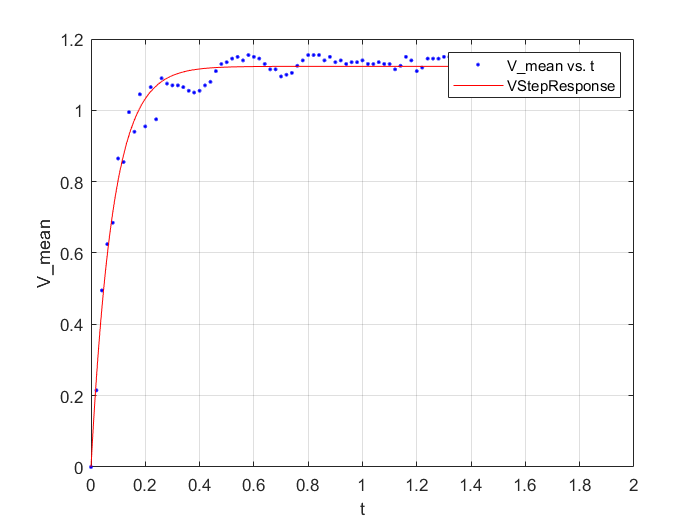

rightFit =      General model:
     rightFit(x) = 300*K*(1-exp(-x/tau))
     Coefficients (with 95% confidence bounds):
       K =     0.00368  (0.003659, 0.003702)
       tau =      0.0815  (0.07705, 0.08595)

taus = [taus; meanFit.tau];
Ks = [Ks; meanFit.K];

rightFit = createStepResponseFit(t, R_vel)

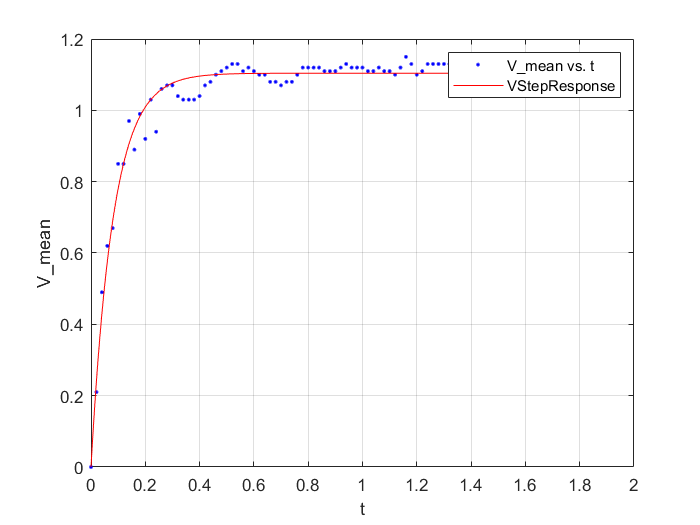

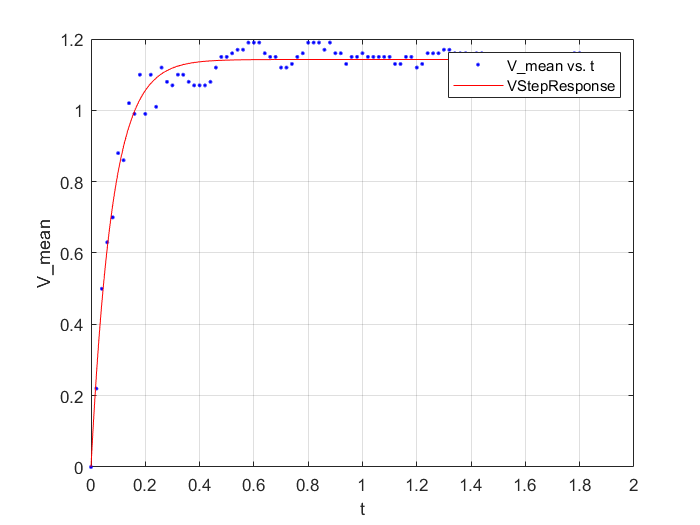

leftFit =      General model:
     leftFit(x) = 300*K*(1-exp(-x/tau))
     Coefficients (with 95% confidence bounds):
       K =    0.003809  (0.003786, 0.003832)
       tau =     0.07766  (0.07318, 0.08213)

leftFit = createStepResponseFit(t, L_vel)


Ks

Ks =     0.0035
    0.0036
    0.0037


K = mean(Ks)

K = 0.0036

taus

taus =     0.0722
    0.0653
    0.0795


tau = mean(taus)

tau = 0.0723


save('New-Rocky-MotorResponse3-2-23', 'tau', 'K', 'taus', 'Ks')
